clc;
close all;
clear variables;

[L, R, C, E, x2e] = nominalni_parametri();
[G, ~, ~, ~, ue] = linearizacija();

M = 0.1 * ue;

sim_file_name = 'ziegler_nichols_frekvencijski_sim';
sim_duration = 10; % sec 
time_step = 1e-3; % sec
open_system(sim_file_name)
warning ('off','all');
out = sim(sim_file_name);

A = out.amplitude.Data(length(out.amplitude.Data));
Ku = 4*M / pi / A;
Tu = 1 / out.frequency.Data(length(out.frequency.Data));
Kp = 0.6 * Ku;
Ti = Tu / 2;
Td = Tu / 8;
Tf = Td / 20;

Interesantno je sto mora minus da se stavi opet zbog negativnog statickog pojacanja

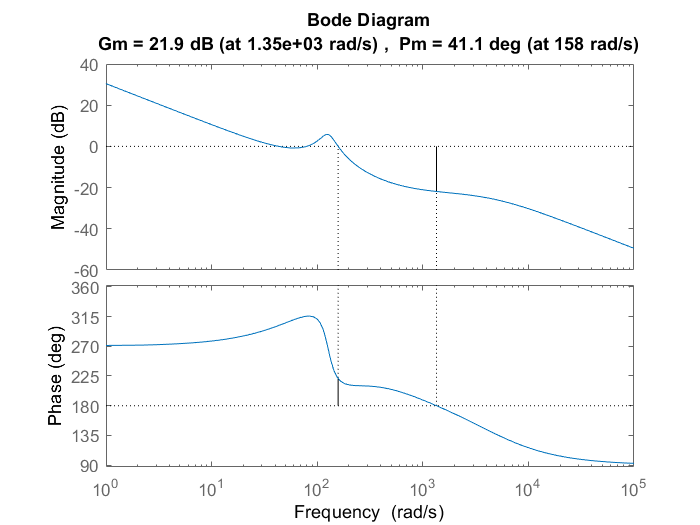

s = tf('s');
K_znf = -minreal(Kp*(1 +1/Ti/s + Td*s/(Tf*s + 1)));
margin(G*K_znf)

close_system(sim_file_name)
